# Analyze heat capacity from DR

This routine is intended at fitting Cp data on Y-substituted TmVO4 acquired with our DR used in the Dynacool PPMS of the Lee lab

## Average data

Import data and compute average of data points taken at same setpoint temperature

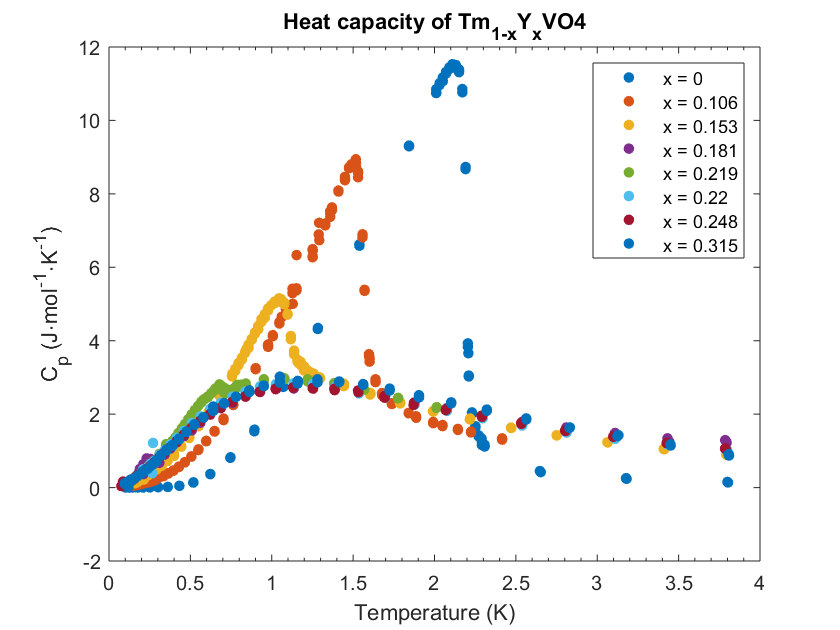

Structure containing averaged data is called avgData


YTmVO4_primary_analysis;

% run script that imports and computes the average of Cp data of all
% desired compositions

### Plot averaged data

#### Plot averaged Cp data for YTmVO4 x<xc

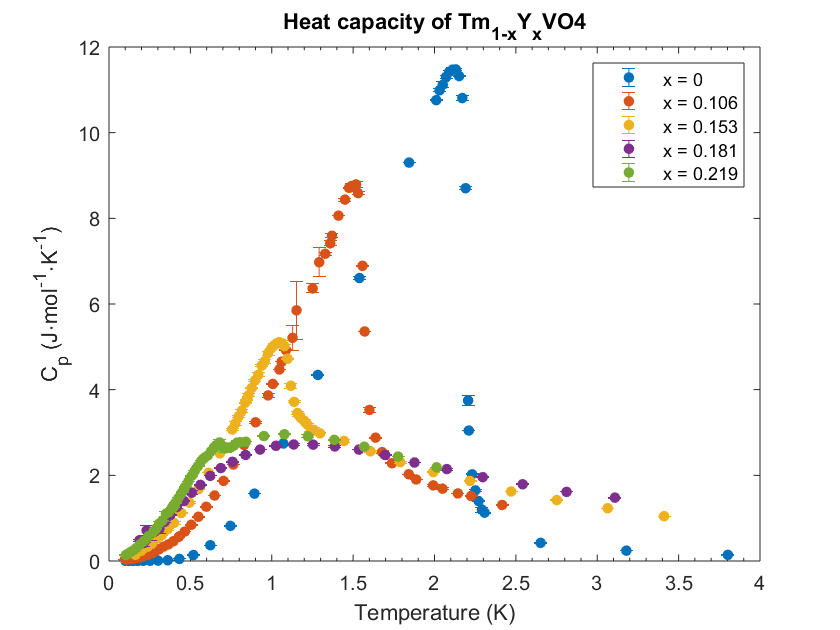

Lord = L-3;% index of the last dataset with Cp jump
plotAvgCp(avgData,dpg,1,Lord)
title(ttlCpY)

#### Plot averaged data for x>xc

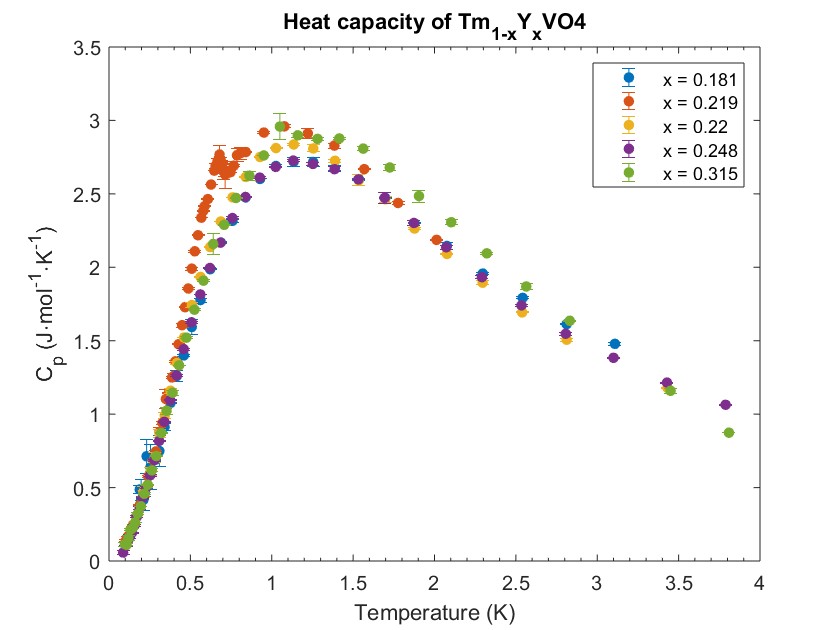

plotAvgCp(avgData,dpg,Lord-1,L)
title(ttlCpY)

### Export averaged Cp data to text file

Lexport = Lord;
% expstr = strings(1,rcidx);
savepath = 'C:\Users\Pierre\Desktop\Postdoc\YTmVO4\YTmVO4_HeatCapacity\YTmVO4_Cp_anaLsis\2018-10-17_YTmVO4_averaged_Cp\';
for i=Lexport:L
    dpg(i);
%     expstr(i) = fullfile(savepath, ['AnaLzeCpDRdoping_2018-11-30_YTmVO4_x=',num2str(dpg(i)),'.txt']);
%     fid = fopen(expstr(i), 'wt');
%     fprintf(fid, '%s\n', ['Exported from AnaLzeCpDRdoping_2018-10-10_YTmVO4_VTmAsO4.mlx on ',date]);  % header
%     fclose(fid);
%     dlmwrite(expstr(i),cat(2,avgData(i).T',avgData(i).Cp',avgData(i).stdCp'),'-append','delimiter','\t')
end

## Fit data

### Fit parameters

Tmfmax = [2.1,1.4,0.9,0.2,0.68];% Maximum temperature of mean-field jump for x=0 to x=0.219
% This is a visual estimate of the temperature below which Cp shows a mean-field jump. It only applies for x<xc.
Tc = [2.2,1.57,1.11,0.24,0.69];% Transition temperature
Tschmin = [2.3,1.7,1.2,0.25,0.7];% temperature above which the data are essentially Schottky-like
x0 = [1e-7 0.5];% range of the pseudospin

### Fit mean-field jump for pure TmVO4

    'Coeffsnorm names'    'Amf'



    8.3047



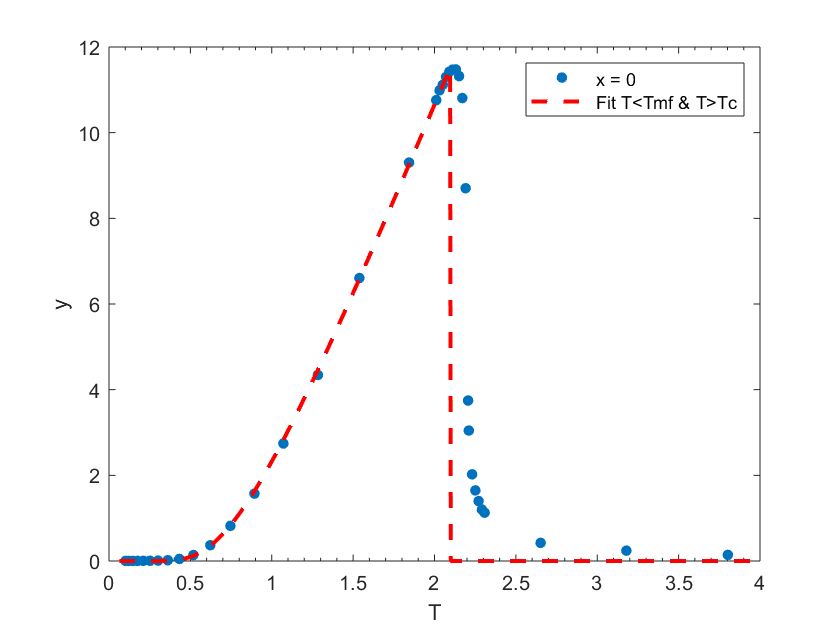

for i=1
    ftmf = fittype(@(Amf,T) fitCpmf(T,Tc(i),Tmfmax(i),Amf),'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [1];% Amf,An,mu,sgm in this order
    opts.Lower = [0];
%     opts.Upper = [Inf Inf 5 5 ];

% Fit mean-field heat capacity jump to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftmf)'])
    [avgData(i).fitmf, avgData(i).ffgof] = fit(avgData(i).T',avgData(i).Cp',ftmf,opts);
    disp(coeffvalues(avgData(i).fitmf))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitmf,'--r');%,'DisplayName','Normal');
    legend({['x = ',num2str(dpg(i))],'Fit T<Tmf & T>Tc'})
end

### Extrapolate fit below Tmfmax up to Tc

G = [0.01:0.01:0.48,0.5-logspace(-2,-15,50)];% range of pseudospin
Tfit = ones(length(Tc),length(G));
for ii=1:2
    avgData(i).fp = @(x) (fmf(x,avgData(i).fitmf.Amf));% Mean-field fitting function below Tmfmin
    Tfit(ii,:) = Tc(ii)*2*G./atanh(2*G);% temperature interval corresponding to the full pseudospin interval
%     fplot(avgData(i).fp,x0);% plot the function on its full interval for each doping level
%     plot(Tfit(ii,:),f(G))% plot Cp fit function on the temperature interval for each doping
end

#### Plot data and extrapolated fit as a function of temperature

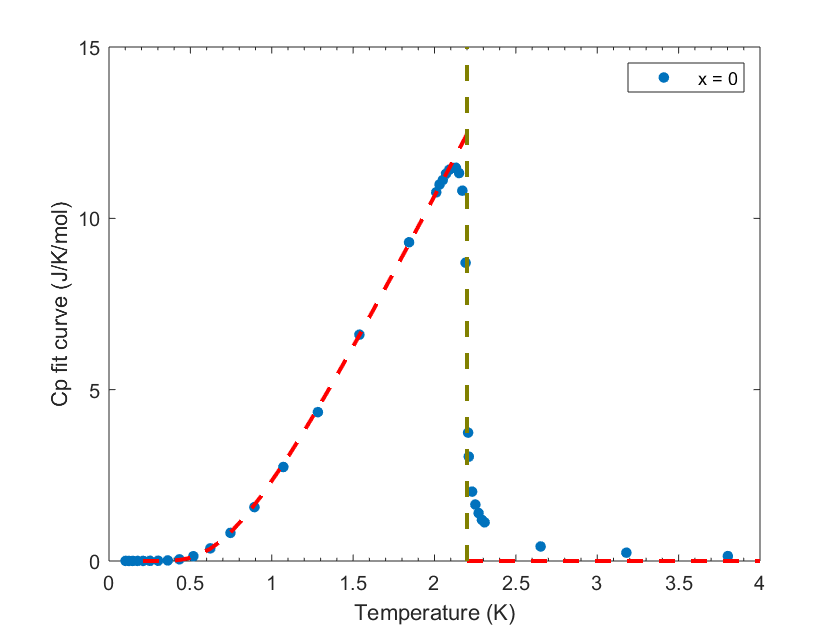

for ii=1
    figure 
    plot(avgData(ii).T,avgData(ii).Cp,'.')
    hold on
    plot(Tfit(ii,:),avgData(ii).fp(G),'--r');%,'DisplayName',['x = ',num2str(dpg(ii))])
    line([Tc(ii),max(xlim)],[0,0],'Color','red','LineStyle','--')
    line([Tc(ii),Tc(ii)],ylim,'Color',[0.5 0.5 0],'LineStyle','--')
    xlabel('Temperature (K)')
    ylabel('Cp fit curve (J/K/mol)')
    legend(['x = ',num2str(dpg(ii))])
hold off
end

# Fit data for x>0 as sum of mean-field jump + Schottky anomaly

This is the initial step where only the data below T_Q was fitted. Since the newest version includes both below and above T_Q and is more accurate, this should be deleted.

## Mean-field Cp + Normal distribution of Schottky anomalies

% Set up normal distribution of Schottky fittype and options.
% ftnorm = fittype(@(An,mu,sgm,x) fnorm(An,mu,sgm,Ttrans,x),...
% ftmfnorm = fittype(@(Amf,An,mu,sgm,x) fmf(x,Amf)+integral(@(D)(fschott(x,Ttrans,An,D,mu,sgm)),0,inf,'ArrayValued',true),...
ftmfnorm = fittype(@(Amf,An,mu,sgm,x) fmf(x,Amf)+fnrmps(An,mu,sgm,Tc(2),x),...
'independent', 'x', 'dependent', 'y' );

opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
% opts.StartPoint = [1 1 1];% An,mu,sgm in this order
% opts.Lower = [1 2 0];
opts.StartPoint = [1 1 1 1];% Amf,An,mu,sgm in this order
opts.Lower = [1 1 2 0];
% opts.Upper = [7 Inf 4 Inf];

% Fit normal distribution of Schottky model to data below Tmfmin
disp(['Coeffsnorm names',coeffnames(ftmfnorm)'])

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    1.0000   36.5899    7.1467    2.8301



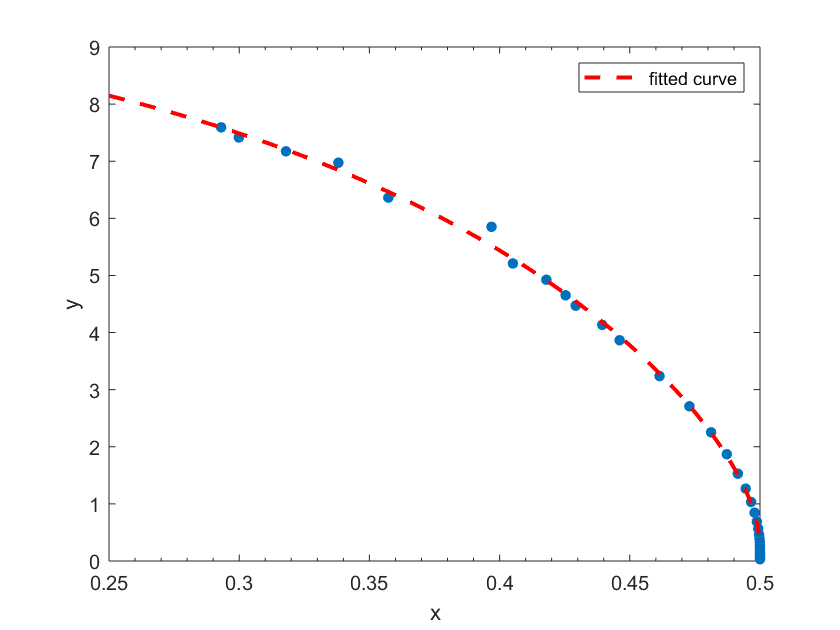

for i=2
    [avgData(i).fitresnorm, avgData(i).gof] = fit(avgData(i).gamma', avgData(i).Cpord', ftmfnorm, opts );
    avgData(i).Coeffsnorm = coeffvalues(avgData(i).fitresnorm);
    disp(avgData(i).Coeffsnorm)
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).gamma', avgData(i).Cpord','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitresnorm,'--r');%,'DisplayName','Normal');
end

## Plot fit for x>0 as a function of temperature

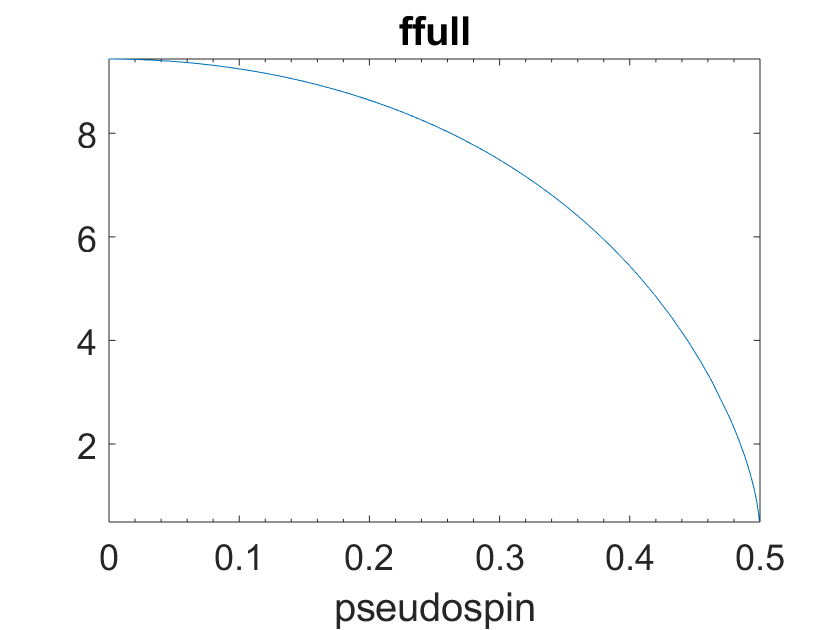

Amf = ones(1,length(avgData(ii)));
An = ones(1,length(avgData(ii)));
mu = ones(1,length(avgData(ii)));
sgm = ones(1,length(avgData(ii)));
for ii=2
    Amf(ii) = avgData(ii).fitresnorm.Amf;
    An(ii) = avgData(ii).fitresnorm.An;
    mu(ii) = avgData(ii).fitresnorm.mu;
    sgm(ii) = avgData(ii).fitresnorm.sgm;
%     fnormps = @(x) integral(@(D)(fschott(x,An(ii),D,mu(ii),sgm(ii))),0,inf,'ArrayValued',true);
%     figure
%     fplot(@(x)fnorm(An(ii),mu(ii),sgm(ii),Tc(ii),x),x0);% plot the function on its full interval
%     xlabel('pseudospin')
%     title('fnorm')
    figure
    ffull = @(x) fmf(x,Amf(ii))+fnrmps(An(ii),mu(ii),sgm(ii),Tc(ii),x);
    fplot(ffull,x0);% plot the function on its full interval
    xlabel('pseudospin')
    title('ffull')
end

## Plot normal distribution of Schottky as a function of temperature

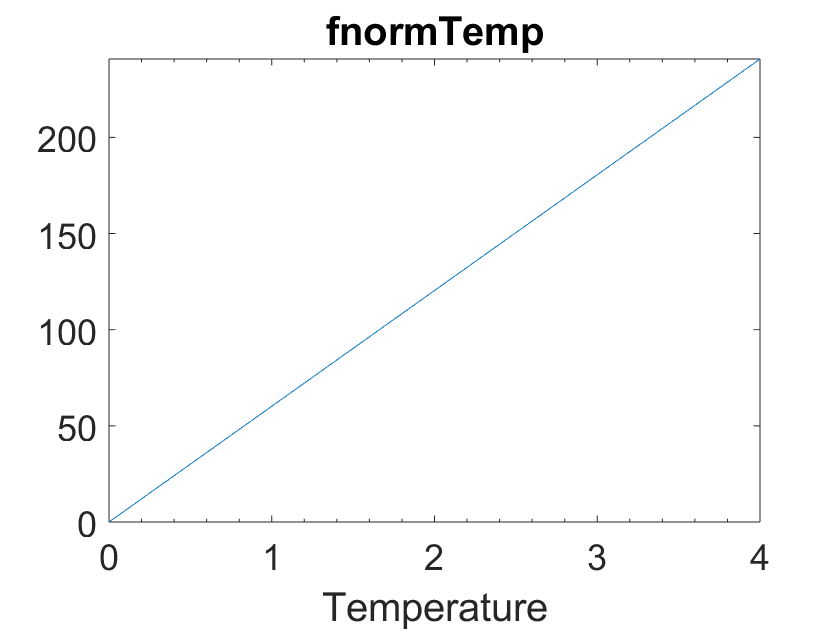

for ii=2;
    fnormTemp = @(x) integral(@(D)(fSchTemp(x,An(ii),D)),0,inf,'ArrayValued',true);
% same as fnormps but as a function of temperature
    figure
    fplot(fnormTemp,[0 4]);% plot the function on its full interval
    xlabel('Temperature')
    title('fnormTemp')
end

## Plot data and full fit as a function of temperature

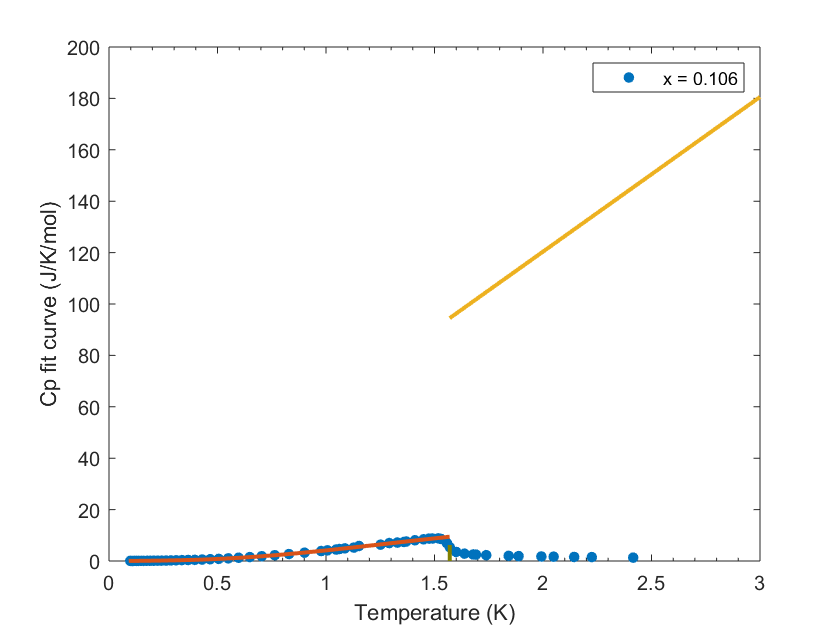

for ii=2
    ht = linspace(Tc(ii),3,20);% range of temperatures above Tc
    figure 
    plot(avgData(ii).T,avgData(ii).Cp,'.')
    hold on
    plot(Tfit(ii,:),ffull(G));%,'DisplayName',['x = ',num2str(dpg(ii))])
    line([Tc(ii),Tc(ii)],ylim,'Color',[0.5 0.5 0],'LineStyle','--')
    plot(ht,fnormTemp(ht));
    xlabel('Temperature (K)')
    ylabel('Cp fit curve (J/K/mol)')
    legend(['x = ',num2str(dpg(ii))])
%     ylim([0 0.5])
    hold off
end

Change fit parameters in order to better fit data above Tc

Perhaps make it a broken segment fit (see Matlab online help for fittype) to include both? Or at least try and fit the data above Tc separately and iterate with the values of the fit parameters below Tc

## Fit normal distribution of Schottky model to data above Tschmin

% ftnorm = fittype(@(An,mu,sgm,T) integral(@(D)fSchTemp(T,An,D,mu,sgm),0,inf,'ArrayValued',true),...
ftnorm = fittype(@(An,mu,sgm,T) fnrmtemp(An,mu,sgm,T),...
    'independent', 'T', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 1];% An,mu,sgm in this order
opts.Lower = [1 0 0];
opts.Upper = [10 4 Inf];

disp(['Coeffsnorm names',coeffnames(ftnorm)'])

    'Coeffsnorm names'    'An'    'mu'    'sgm'



    9.9028    1.8887    0.0030



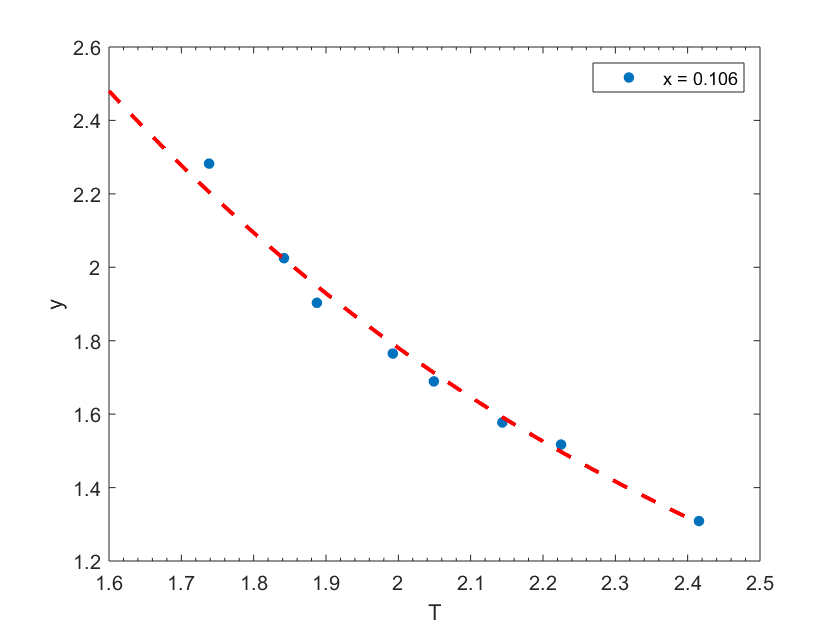

for i=2
    [avgData(i).fitSchNorm, avgData(i).SNgof] = fit(avgData(i).Tsch', avgData(i).Cpsch', ftnorm, opts );
    disp(coeffvalues(avgData(i).fitSchNorm))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).Tsch', avgData(i).Cpsch','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitSchNorm,'--r');%,'DisplayName','Normal');
end

## Fit full curve piecewise with *normal* Schottky PDF

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    4.9012    5.2241    4.4751    2.1411



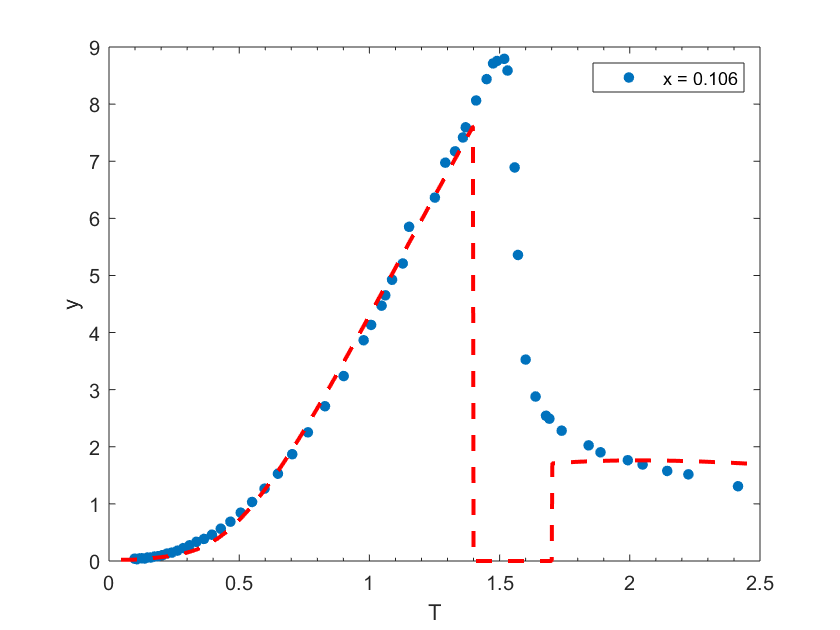

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    1.2050    7.6543    2.7464    0.8957



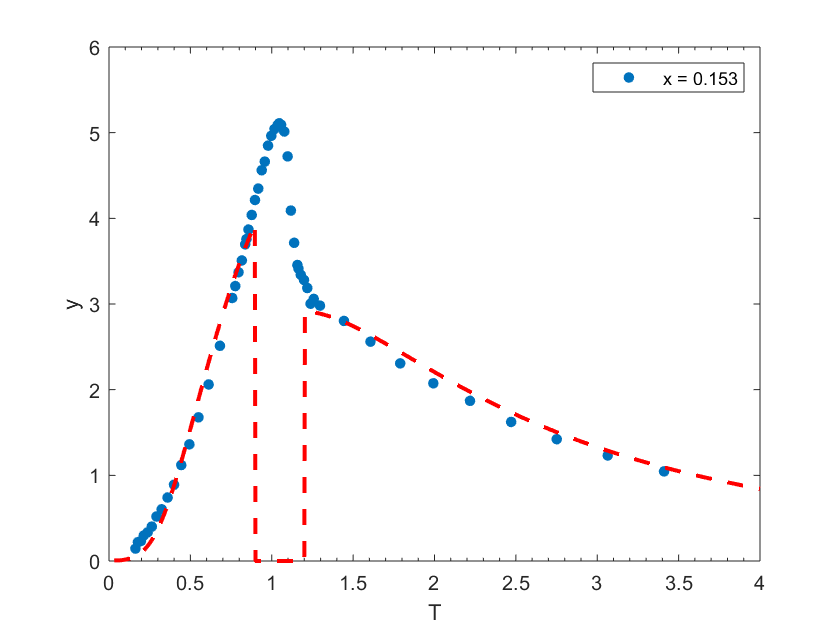

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    0.0577    9.5597    2.3567    1.6505



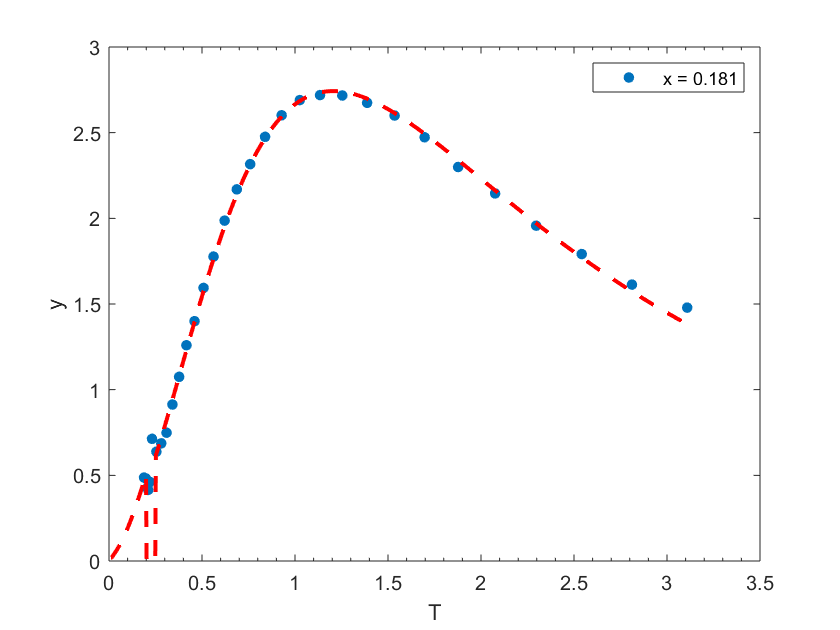

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    0.2041    9.0494    2.3455    1.1537



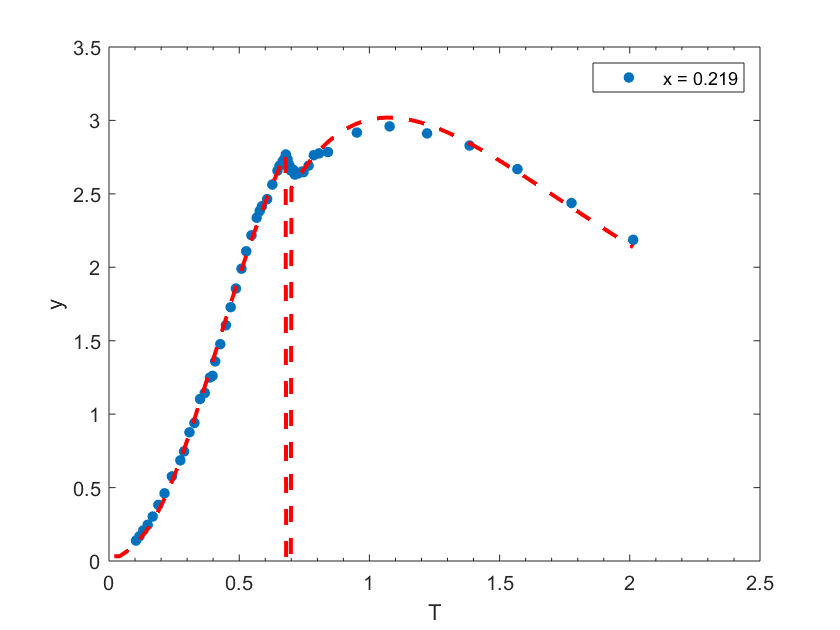

for i=2:5
%     ftfull = fittype(@(An,mu,sgm,T) fitCpdop(T,Tschmin(i),An,mu,sgm),...
%     ftfull = fittype(@(Amf,An,mu,sgm,T) fitCpdop(T,avgData(i).gamma,Tmfmax(i),Tschmin(i),Amf,An,mu,sgm),...
    ftfull = fittype(@(Amf,An,mu,sgm,T) fitCpnrm(T,Tc(i),Tmfmax(i),Tschmin(i),Amf,An,mu,sgm),...
    'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
%     opts.StartPoint = [1 1 1];% Amf,An,mu,sgm in this order
%     opts.Lower = [0 0 0];
    opts.StartPoint = [1 1 1 1];% Amf,An,mu,sgm in this order
    opts.Lower = [0 0 0 0];
%     opts.Upper = [Inf Inf 5 5 ];

% Fit normal distribution of Schottky model to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftfull)'])
    [avgData(i).fitfull, avgData(i).ffgof] = fit(avgData(i).T', avgData(i).Cp', ftfull, opts );
    disp(coeffvalues(avgData(i).fitfull))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitfull,'--r');%,'DisplayName','Normal');
    legend(['x = ',num2str(dpg(i))])
end

## Fit full curve piecewise with *uniform* Schottky PDF

    'Coeffsnorm names'    'Amf'    'Au'    'di'    'df'



    1.1616    2.7702    1.3939    4.1094



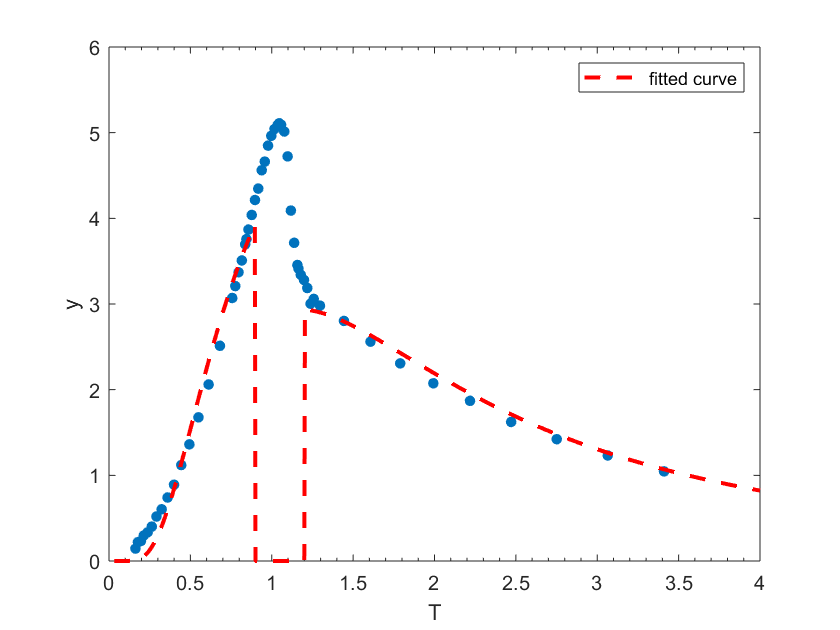

for i=3
    ftfull = fittype(@(Amf,Au,di,df,T) fitCpunif(T,Tc(i),Tmfmax(i),Tschmin(i),Amf,Au,di,df),...
    'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [1 1 1 1];% Amf,An,mu,sgm in this order
    opts.Lower = [0 0 0 0];
%     opts.Upper = [Inf Inf 5 5];

% Fit normal distribution of Schottky model to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftfull)'])
    [avgData(i).fitfull, avgData(i).ffgof] = fit(avgData(i).T', avgData(i).Cp', ftfull, opts );
    disp(coeffvalues(avgData(i).fitfull))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitfull,'--r');%,'DisplayName','Normal');
end

## Fitting functions

function y = fmf(x,Amf)% Mean-field expression of heat capacity as a function of pseudospin x
    y = Amf*(atanh(2*x)).^2.*(1-4*x.^2)./(1-(1-4*x.^2).*atanh(2*x)./(2*x));
end

function y = fschps(x,Ttrans,A,D)% Schottky anomaly as a function of pseudospin x
    y = A*(D./(2*Ttrans*2*x./atanh(2*x))).^2.*sech(D./(2*Ttrans*2*x./atanh(2*x))).^2 ;
end

function y = fnrmps(An,mu,sgm,Ttrans,x)% Normal PDF of Schottky anomaly as a function of pseudospin x
    y = integral(@(D)(fschps(x,Ttrans,An,D).*normpdf(D,mu,sgm)),0,inf,'ArrayValued',true);
end

function y = funifps(Au,di,df,Ttrans,x)% Uniform PDF of Schottky anomaly as a function of temperature T
    y = integral(@(D) fschps(x,Ttrans,Au,D),di,df,'ArrayValued',true);
end

function y = fSchTemp(T,A,D)% Schottky anomaly as a function of temperature T
    y = A*(D./(2*T)).^2.*sech(D./(2*T)).^2;
end

function y = fnrmtemp(An,mu,sgm,T)% Normal PDF of Schottky anomaly as a function of temperature T
    y = integral(@(D)fSchTemp(T,An,D).*normpdf(D,mu,sgm),0,inf,'ArrayValued',true);
end

function y = funiftemp(Au,di,df,T)% Uniform PDF of Schottky anomaly as a function of temperature T
    y = integral(@(D) fSchTemp(T,Au,D),di,df,'ArrayValued',true);
end

function y = pseudospin(T,Ttrans,Tmf)
%%% calculate pseudospin as a function of temperature T from T=0 to T=Tmf
%%% for a given transition temperature Ttrans
    Tord = T(T<Tmf);
    y = 0.2*ones(1,length(Tord));% initialize pseudospin array
    g = @(t) fzero(@(x) Ttrans*2*x./atanh(2*x)-t,[1e-7 0.5]);
    for jj=1:length(y)
        y(jj) = g(Tord(jj));
    end
end

The expression of the anonymous function inside fzero is that of a reduced temperature defined as T_caluclated - T_measured, such that it takes the value zero when T_calculated = T_measured. This expression results from inverting the self-consistent equation 2*gamma = th(beta*gamma/2), where gamma is the total pseudospin and beta is the inverse temperature beta = 1/(k_B*T). Therefore, when the function takes the value zero, the correponding abscissa is the value of the total pseudospin at the measured temperature.

Note: the equation 2*gamma = th(beta*gamma/2) is for a reduced beta = beta/beta_c such that k_B*T_c/J_0 = 1/4. In order to get the actual value of the critical temperature, one needs to multiply k_B*T by 4*T_c. The factor 2 in the numerator of the function results from the multiplication by 4 and the factor Tc is the actual value of the transition temperature (estimated visually).


function y = fitCpmf(T,Ttrans,Tmf,Amf)
%%% Fitting mean-field heat capacity jump as a function of temperature below Tmf 
    y = zeros(size(T));
    gamma = pseudospin(T,Ttrans,Tmf);
    y(T<Tmf) = fmf(gamma,Amf);%
    y(T>Ttrans) = 0;
end

function y = fitCpnrm(T,Ttrans,Tmf,Tsch,Amf,An,mu,sgm)
%%% Fitting function for heat capacity as a combination of : 
%%% a mean-field jump and *normal* Schottky distribution below Tmf 
%%% a *normal* Schottky distribution above Tsch
    y = zeros(size(T));
    gamma = pseudospin(T,Ttrans,Tmf);
    y(T<Tmf) = fmf(gamma,Amf) + fnrmps(An,mu,sgm,Ttrans,gamma);%
    y(T>Tsch) = fnrmtemp(An,mu,sgm,T(T>Tsch));
end

function y = fitCpunif(T,Ttrans,Tmf,Tsch,Amf,Au,di,df)
%%% Fitting function for heat capacity as a combination of: 
%%% a mean-field jump and *uniform* Schottky distribution below Tmf 
%%% a *uniform* Schottky distribution above Tsch
    y = zeros(size(T));
    gamma = pseudospin(T,Ttrans,Tmf);
    y(T<Tmf) = fmf(gamma,Amf) + funifps(Au,di,df,Ttrans,gamma);%
    y(T>Tsch) = funiftemp(Au,di,df,T(T>Tsch));
end

Note: all these functions need to be defined **before** the function is called for fitting